# Authors: Marta Barriendos & Ana Garcia Armada, Univesidad Carlos III de Madrid

# TIME AND FREQUENCY SYNCHRONIZATION OF THE OFDM SIGNAL

## Introduction

Time and frequency synchronization are critical in OFDM-based systems, such as WLAN receivers, due to the sensitivity of OFDM to timing errors and frequency offsets. Proper synchronization ensures that the receiver correctly interprets the transmitted data, which is crucial for maintaining communication integrity and performance.

#### Importance of Time and Frequency Synchronization

- **Time Synchronization**: It aligns the receiver with the start of the data packet and each OFDM symbol. Without this, the receiver could sample data at the wrong points, leading to inter-symbol interference (ISI) or loss of data. Misalignment in time affects the ability to extract information from each OFDM subcarrier correctly.

- **Frequency Synchronization**: Compensates for frequency offset between the transmitter and receiver due to oscillator differences or Doppler shifts. Frequency errors cause inter-carrier interference (ICI), which can significantly degrade performance by causing the subcarriers to overlap, distorting the transmitted signal.

In order to better understand the process, we can analyze the block diagram of an OFDM system, including the new blocks of synchronization in time and frequency. 

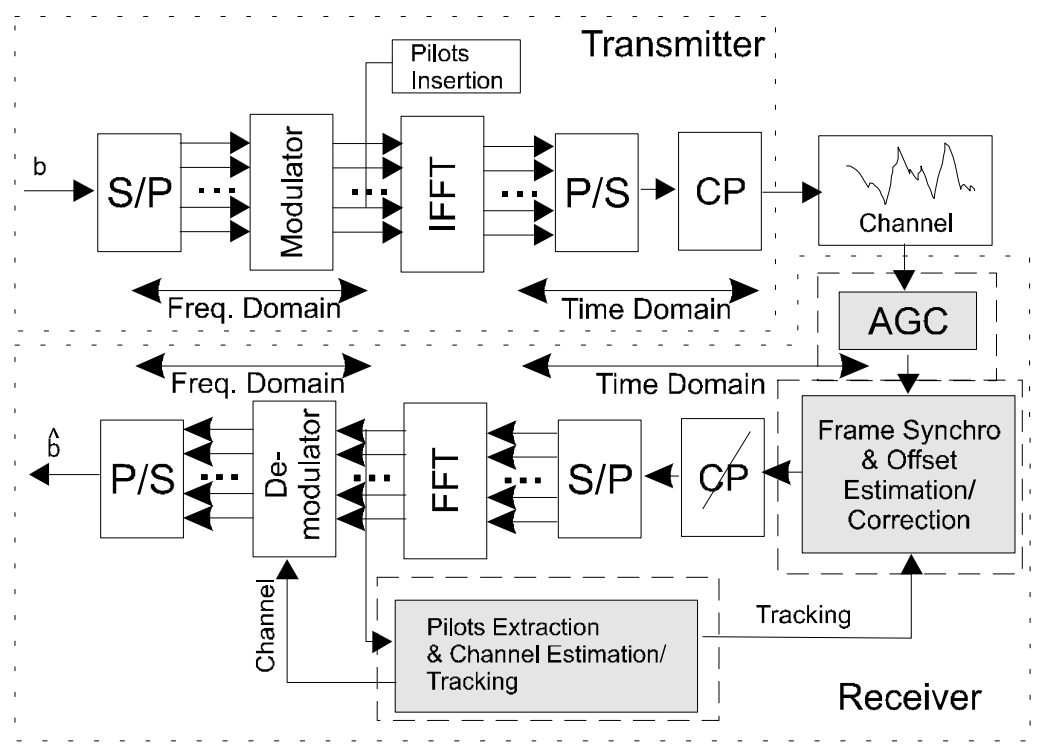

(Design and Implementation of Synchronization and AGC for  OFDM-based WLAN Receivers,  *Víctor P. Gil Jiménez,  M. Julia Fernández-Getino García, Francisco J. González Serrano, and Ana García Armada*)

The overall process is the same as in the previous module, if we remember the different steps: at the transmitter, binary stream ***b*** is converted from serial to parallel, and modulated by using the adequate complex  mapping. Then, pilots are inserted and the IFFT is performed in order to obtain the time domain signal, which is converted back to serial. And finally, the Cyclic Prefix (CP) is included. The signal travels across the channel that corrupts it (attenuation, rotation, distortion) and then it **arrives to the  receiver** where the** signal has to be synchronized in time and frequency, **after which the remaining processes have to be carried out  inversely.

## Index

- Generating the WLAN packet following the IEEE 802.11a standard.

-  Channel transmission.

- Time and frequency synchronization of the OFDM signal. 

- Data demodulation. 

## 1. Generating the WLAN packet following the IEEE 802.11a standard.

To begin this second module, we are going to generate a packet according to the IEEE 802.11a standard, which defines the specifications for WLAN (Wireless Local Area Networks) and uses OFDM as the modulation technique. Once we generate these packets, we will carry out their transmission, reception, synchronization, and demodulation, studying in detail the process of time and frequency synchronization of the OFDM signal.

Let's start with a brief explanation of the parameters we are going to define in the code. 

First, as number of subcarriers (***N***), we have chosen 64, this is the number used by the IEEE 802.11a. Of these, 48 are used for data transmission, 4 are pilots for phase tracking, and 12 are guard bands to avoid interference. 

***MaxAnnado***  is set to 30, this is the maximum number of samples added before the signal, basically it refers to padding or pre-guard intervals that might be added to the signal before transmission. It helps manage synchronization and guard time at the receiver side. 

***LP***  equal to 80 refers to the packet length in samples, including the OFDM symbol duration plus the cyclic prefix. In IEEE 802.11a, each OFDM symbol is 80 samples long (64 subcarriers + 16 cyclic prefix). As we have explained, the cyclic prefix is 16, so its parameter is defined by ***NPC*** (Number of cyclic prefix samples), as we saw in the previous module, this will help mitigate inter-symbol interference (ISI) caused by multipath propagation. ***PGI***** and *****PGF*** are the initial and final guard intervals that can be added to the packet. 

Since IEEE 802.11a operates in the 5 GHz band with a bandwidth of 20 MHz, this will be the value of ***BW, ***and defines the total frequency range available for the 64 subcarriers. Regarding the subcarrier spacing (***DeltaF***), this is determined by the total bandwidth divided by the number of subcarriers. For 20 MHz bandwidth and 64 subcarriers, the spacing is 312.5 kHz ($\Delta F=\frac{20\;\textrm{MHz}}{64\;s\textrm{ubcarriers}}=312\ldotp 5\;\textrm{KHz}$). And, the symbol duration (***T***) is the inverse of the bandwidth divided by the number of subcarriers. For 64 subcarriers and 20 MHz bandwidth, the symbol period is 3.2 µs.

Along this module, since we are interested in the part of synchronization and not in the transmission through the channel itself, we are going to use an ideal channel, which is why we define the variable, ***IDEAL.***

Another important part of the implementation are the detection  thresholds, which ase used for different stages of the signal processing, for example,  the detection threshold for signal detection or packet detection,***thres_det (0.95)***, this is a good value because the maximum value of the correlation is 1, so a value of 0.95 is a high correlation value to determine that we have detected the signal***. ***The threshold for estimating frequency offset is ***thres_offset, ***the value itself is 0.4, which means that we can have a difference between the transmission frequency and the reception frequency of 40% before doing corrections, therefore, we allow a certain error between frequencies. The re-estimation threshold for correcting the frequency offset during recepcion ***thres_re***, this indicates when it is necessary to re-estimate the offset because the displacement has changed enough, the value must be similar to ***thres_offset*** to guarantee that any significant change can be detected and corrected. And finally, the threshold for down-synchronization, which is related with symbol boundary detection, is ***thres_low***.

The data rate (***R***) is set to 12 Mbps, which in IEEE 802.11a corresponds to QPSK modulation with 1/2 coding rate. And the Modulation factor (***factor_mod***) is set to 2, this corresponds to QPSK modulation, where each symbol carries 2 bits (hence the factor of 2).

Finally, the variables ***partial*** (Error counter) and ***counterPsinSync*** (Non-synchronized packets counter) track the number of errors in packet reception and the number of packets that failed to synchronize, respectively, likely used for performance metrics.

These parameters are defined below: 

N = 64; 						
MaxAnnado = 30;			
LP = 80;						
NPC = 16;					
PGI = 0;         
PGF = 0;            
BW = 20e6;					
DeltaF = BW/N;				
T = N/BW;					
IDEAL = 0;					
thres_det = 0.95;			
thres_offset = 0.4;		
thres_re = 0.4;			
thres_low = 0.8;       
Rate = 12;					
factor_mod = 2;			
partial = 0;				
counterPsinSync = 0;	

Npackets=1; %Number of packets we want to send
Ndata =960; %Number of bits per packet
snrdB=25; %SNR in dB
Epsilon=0.25; %Offset of frequency separation between subcarriers. 

**Generating the packet:**

Now, we are going to generate the bits for the packet we are going to send, and for that, we are using a random function (***randn***). As we have explained before, following the IEEE standard for our OFDM signal, we will have 4 subcarriers for pilots signals in fixed positions, define by the vector ***pilots. ***The rest of the 48 subcarriers will be used for data, and their positions are also defined in a new vector called ***nopilots***. Moreover, we are converting the input bit array (***input_data***) into a string, for easier manipulation, stripping out spaces and keeping only the actual bits, getting the final bit signal (***inputc_data***).

On the other hand, we are defining a number of bits transmitted (codified) per OFDM symbols of 96. Since we are using a QPSK modulation, each sucarrier can carry 2 bits of data per symbol, and since we have 48 data subcarriers, $\textrm{bits}\;\textrm{per}\;\textrm{symbol}=48\;x\;2=96\;\textrm{bits}$. Knowing this, we calculate the number of symbols that we need to send all the bits (***n_symb***), that will be 10, because we want to send 960 bits. 

input_data = randn(1,Ndata)>0.5;			% Generating bits

% Pilots positions
pilots = [6 20 34 48];
nopilots = [1:5 7:19 21:33 35:47 49:52];

aux = num2str(input_data);%Change from  [1 1 1 1]--> '1 1 1 1'
inputc_data = aux(1:3:end); %We only take the 1s and not the blank spaces

n_bits = length(inputc_data); % Calculate how many bits we are sending to the upper layer

bits_disp =96; % Number of bits codified in each symbol, due to the Rate, R=12
n_symb = n_bits/bits_disp; % Number of necessary symbols
n_symbs = ceil(n_symb); % If the division is not exact, we need to round up the value obtained


Now, once we have generated the input data, we perform its representation to check the shape of the signal we are going to transmit, verifying how it is composed by a stream of bits (0s and 1s).

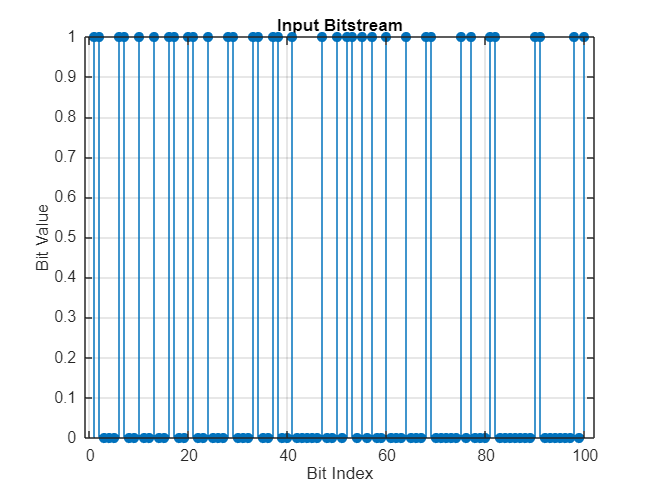

% 1. Input Bitstream
figure;
stem(input_data(1:100), 'filled');
title('Input Bitstream');
xlabel('Bit Index');
ylabel('Bit Value');
grid on;

Our next step is to generate the complete IEEE 802.11a packet, by first adding the necessary headers and then modulating the data into OFDM symbols, following the standard specifications.

Firstly, we generate the packet header using the function ***generateheader80211a. ***The variable ***size_ ***calculates the size of the packet in bytes by dividing the total number of bits (***n_bits***) by 8, and rounding up with ***ceil*** to ensure enough space for the data. Secondly, we generate the signal or the entire packet (***packet***), appeding to the previous header the signal generated by the function ***fillsignal(Rate,tam).***

Then, for each OFDM symbol, the data is modulated using the ***bits2data80211a*** function, which converts input bits (***inputc_data***) into symbols based on the modulation scheme. A total of 52 subcarriers are used, of which 48 are data subcarriers and 4 are pilot subcarriers (subcarriers 6, 20, 34, and 48). These pilot subcarriers are set to known values (+1 or -1) to assist in channel estimation and synchronization.The remaining 48 data subcarriers are filled with modulated data. For each symbol, the function ***generatesymbol80211a ***creates the **OFDM symbol** from the modulated data, and it is appended to the packet.

packet = generateheader80211a;% Create the header

% Calculating the size of the packet in bytes
size_ = ceil(n_bits/8);

packet = [packet fillsignal(Rate,size_)];

%We assume we do not need padding

for n_s = 1:n_symbs
 % Modulating the data
 dataini = bits2data80211a(inputc_data,Rate,n_s,0);
 data = zeros(1,52);
 % Adding pilots
 data(6) = 1; 
 data(20)= 1;
 data(34)= 1;
 data(48)= -1;
 % Filling the signal with the data
 data(nopilots) = dataini;
 packet = [packet generatesymbol80211a(data)];   % Adding the symbol to the packet with the header

end 
packet_o=packet; %This is the OFDM signal

Now, we compute the header of the packet, using the function ***generateheader80211a. ***When representing it, we can see how the preamble consists of a known training sequence with constant amplitude, to make easier the detection and processing, since this sequence will be used for synchronization and channel estimation. After the constant sequence (preamble), the header is presented. This second part includes information about the data rate and length of the payload, and although it looks more random than the header, it continue exhibiting a more regular pattern compared to the actual data symbols (presented at the right plot)

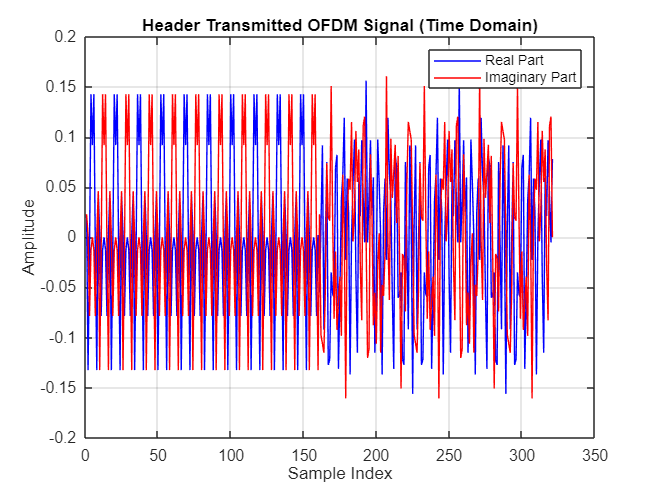

%Header
packet22 = generateheader80211a;
figure;
plot(real(packet22), 'b');
hold on;
plot(imag(packet22), 'r');
title('Header Transmitted OFDM Signal (Time Domain)');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Real Part', 'Imaginary Part');
grid on;

Then, the complete packet with its header and corresponding data is presented. As we can see, these symbols are modulated using OFDM, which is why a more complex and varying amplitude pattern can be observed after the initial 160 samples (preamble) and the header

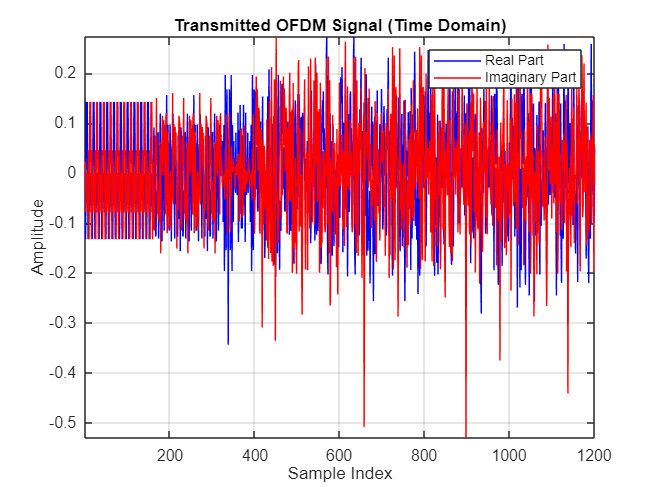

% 2. Transmitted OFDM Signal (Time Domain)
figure;
plot(real(packet_o), 'b');
hold on;
plot(imag(packet_o), 'r');
title('Transmitted OFDM Signal (Time Domain)');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Real Part', 'Imaginary Part');
axis tight
grid on;

Finally, it is also useful to represent the spectrum of the packet, that contains the OFDM signal. As we can see, the spectrum reflects the common shape of a noisy OFDM signal, which reflects the fact that the packet has been properly generated. 

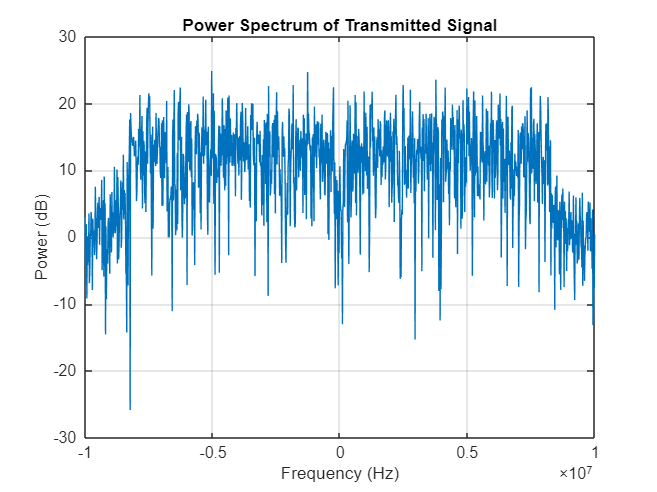

% 3. Power Spectrum of Transmitted Signal
figure;
psd_signal = fftshift(abs(fft(packet_o)).^2);
freq = linspace(-BW/2, BW/2, length(psd_signal));
plot(freq, 10*log10(psd_signal));
title('Power Spectrum of Transmitted Signal');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
grid on;

Now, we generate the signal ***ref***, selecting a part of the transmitted packet, specifically of the OFDM symbol that contains the sequences **T1** and **T2** (training symbols used for synchronization and channel estimation). 161 is the index where the **SIGNAL field** ends, and the first OFDM symbol begins, we know this because in the IEEE 802.11a standard, the first part of the packet is the preamble,with a total length of 320 samples, which is used for synchronization, channel estimation, and rate signaling. The Short Training Sequence (**STS**) is composed by 160 samples, and the Long Training Sequence (**LTS**) the other 160 samples. This is why we are removing the first 160 samples, moreover, we also want to remove the 32 next samples that correspond to the cyclic prefix and contain redundant data for preventing inter-symbol interference (ISI). So, the extracted segment is 64 samples long, which is the OFDM symbol length (N = 64). Finally, we perform the FFT to convert the symbol to the frequency domain, which is necessary for further processing for estimating the channel. 

In the next line, we reorder the frequency bins, removing the DC subcarrier that doesn't carry data (index 1) and retaining only the active subcarriers (from 2-27 and 39-64), since the rest are reserved as guard bands and discareded in this step.

Finally, we take the real part and introduce the frequency ***offset(PutOffset2(packet_o,Epsilon,NPC,LP)***) to the signal, which will be later compensated in the receiver during synchronization. Frequency offset can cause inter-carrier interference (ICI) in OFDM systems, so compensating it correctly is critical.  We are adding this offset just to **simulate a typical situation that occurs in real systems **when there is a mismatch between transmitter and receiver oscillators, later we will compensate this in the receiver during synchronization, evaluating the performance of our system.

%We select the OFDM symbol that has the T1, T2 and we remove the cyclic prefix (161+32)
ref = fft(packet_o(161+32:161 + 32 + 63),N);
% Reordering
ref = ref(2:end); 
ref = [ref(1:26) ref(38:end)];
ref = real(ref);

% We put the offset
packet_e = packet_o .* exp(2*j*pi*Epsilon*(1/N)*(1:length(packet_o)));

Another useful representation is to plot the effect that the frequency offset has in the original signal. Once the offset has been added, it can be seen in the figure below, how it causes a variation in the amplitude and phase of the signal, that is inconsistent with the original preamble (constant through its length of 160 samples), leading to the observed distortion. In fact, it is causing a phase rotation over time, which changes the expected constant pattern.

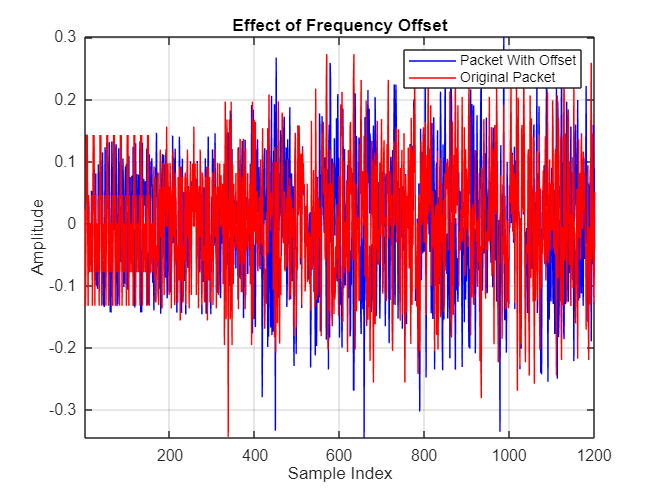

% 4. Effect of Frequency Offset
figure;
plot(real(packet_e), 'b');
hold on;
plot(real(packet_o), 'r');
title('Effect of Frequency Offset');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Packet With Offset', 'Original Packet');
grid on;
axis tight;

## 2. Channel transmission

The following step is to send our packet through a channel. We are simulating an **ideal channel** with the variable ***taps*** set to 1. This means that the channel does not introduce any distortion or attenuation to the signal; it simply passes the input signal through unchanged. Then, we upsample the signal (***inputup***), because the input signal has a sampling rate of 20 MHz, and the channel sample's rate is 80 MHz (4 times higher), so we increase the sampling rate of the signal to match the channel's sample rate. 

The upsampled signal ***inputup*** is then passed through the ideal channel using convolution with the ***taps*** defined earlier. Since the variable ***taps*** is set to 1, this convolution effectively means that the output signal (***outup***) is equal to the input signal. In a real channel with non-ideal conditions, the convolution would introduce various effects depending on the channel's impulse response.

After processing the signal through the channel, the output signal is downsampled back to its original sampling rate by taking every fourth sample of the ***outup*** signal.

%Sending the signal through the ideal channel, taps=1: 
taps = 1; % Canal ideal
H = ones(1,N);

%Upsampling the input signal
inputup = upfirdn(packet_e,[1 1 1 1],4,1);

% Send the signal through the channel
outup = conv(inputup,taps);

% Downsampling the signal to the the original frequency
out = outup(1:4:end);
packet = out(1:length(packet_e));

In the following figure, we present the ideal channel impulse reponse that we have generated, and though which the signal is sent.

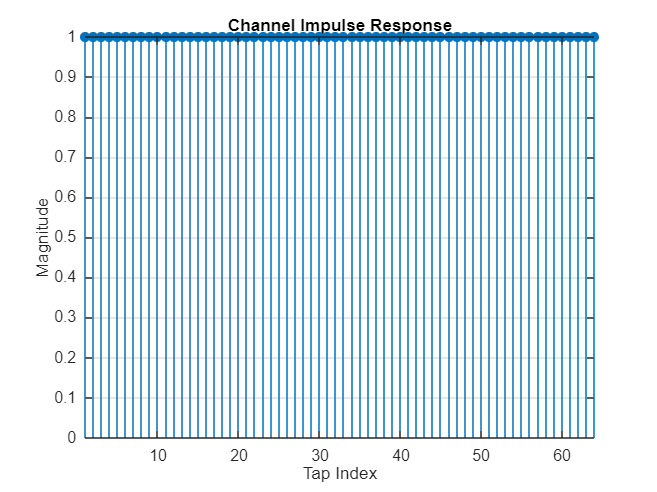

% 5. Channel Impulse Response
figure;
stem(abs(H), 'filled');
title('Channel Impulse Response');
xlabel('Tap Index');
ylabel('Magnitude');
grid on;
axis tight;

Now,  we create a  variable ***annado*** that generates a random number of samples to be added before the actual signal. This value is determined by multiplying a maximum number of samples (***MaxAnnado***`, `that in our case is defined at the initial part of the code as 30) by a random value between 0 and 1, and then rounding it to the nearest whole number. This simulates the presence of noise or random fluctuations that may occur before the signal starts, which is important for the detection algorithms in the receiver.

Since ***varnoise*** is set to zero, because our channel is ideal, the generated noise will effectively be zero. Therefore, ***annadonoise*** will consist of zero samples.

%Channel=IDEAL;

varnoise = 0;
packet_r = packet;

% First we add some samples and the initial part of the signal to be able to make the detection.
annado = round(MaxAnnado * rand); % 
annadonoise = (sqrt(varnoise)/2) * (randn(1,annado) + j*randn(1,annado)); % We establish the same noise that has the system
packet_tx = [annadonoise packet_r];  % This will be the packet that arrives to the receiver


Lastly, we can represent the received OFDM Signal in the time domain. Looking at the graph below, it is clear that the signal has been distorted by the frequency offset, as the preamble reflects, since instead of having a constant pattern, it has a variable amplitude and phase rotation

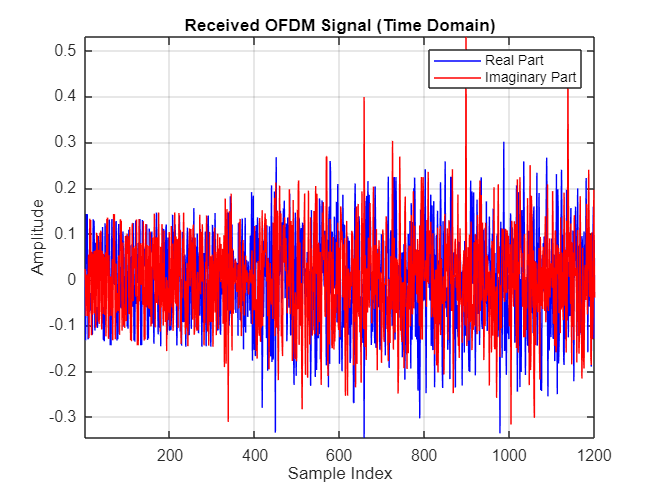

% 6. Received OFDM Signal (Time Domain)
figure;
plot(real(packet_r), 'b');
hold on;
plot(imag(packet_r), 'r');
title('Received OFDM Signal (Time Domain)');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Real Part', 'Imaginary Part');
grid on;
axis tight;

## 3. Time and frequency synchronization of the OFDM signal. 

Now, we are starting the synchronization part. First of all, before starting the synchronization process, we define the number of short samples that are symmetric, in our case ***L=32***. This will be the size we decide for the blocks on which we will apply the correlation; that is, we will perform the correlation between a block of 32 samples and the next one of the same size. It is important to choose this value based on the characteristics of the system, in order to conduct an effective analysis of the signal through the correlation of short and symmetric segments. For example, using this value, that generates a short segment, helps capture rapid variations in the signal that might be missed if a larger block (for bigger Ls) is used.

A loop runs through a range that covers potential starting positions, for detecting the signal within the received packet, the initial part of the signal could be from 1, to the end of the preamble (320) plus the noise samples we have added for detection (***annado***), adjusting the value to the blocks of ***L=32*** that we are using (this means substracting 2L to adjust the iterator of the loop). For each position (***index***), it computes two key metrics:

- **Pnoisy**: This array calculates the cross-correlation between the conjugate of the incoming signal samples and a subsequent set of samples. It measures the similarity between the signal and its shifted version, which is essential for detecting timing and phase information.

- **Rnoisy**: This array computes the power of the incoming signal over a defined window, which is necessary to normalize the correlation measurements. It captures the energy present in the signal segment being analyzed.

The code then calculates the metric ***Mnoisy***, which is a ratio of the squared magnitude of the correlation (***Pnoisy***) to the squared power (***Rnoisy***). This metric is vital for thresholding and detecting signal presence among noise.

The phase of the correlation (***phinoisy***) is derived from ***Pnoisy***, and from this, the frequency offset (***deltafnoisy***) is calculated. This provides an estimate of how much the signal frequency deviates from the expected frequency, crucial for synchronization.

The code identifies indices where ***Mnoisy*** exceeds predefined thresholds for detection (***thres_det*** for signal detection and ***thres_offset*** for frequency offset estimation). These thresholds are crucial for determining valid signal presence against noise:

- It checks if any indices met the detection criteria. If not, it looks for the maximum value of ***Mnoisy*** to find a potential starting point.

- It then modifies ***Mnoisy ***to help locate when the values fall below a lower threshold (***thres_low***), indicating the end of the detected signal.

- The synchronization points (***imr2***) are calculated based on these metrics, ensuring that the process effectively aligns with the main signal segment.

The estimated frequency offset is extracted (***epsilon_est***), and adjustments are made based on the index to determine the appropriate synchronization position, accounting for short symbols that were added initially. This step is important for fine-tuning the signal processing, particularly since actual implementations may handle synchronization differently.

L = 32;	

% We calculate P(d) y R(d)
for index = 1:320+annado-2*L-1
	Pnoisy(index) = sum(conj(packet_tx(index:index+L-1)).*packet_tx(index+L:index+2*L-1));
	Rnoisy(index) = sum(abs(packet_tx(index+L:index+2*L-1)).^2);
end % 

Mnoisy = (abs(Pnoisy).^2)./(Rnoisy.^2);

phinoisy = angle(Pnoisy);

deltanoisy = phinoisy/(pi*T);

epsilonnoisy_e = deltanoisy/DeltaF;

%Finding the initial position of the signal, and frequency offset

[mmr,imri] = find(Mnoisy > thres_det); %When Mnoisy exceeds this threshold, it suggests that the signal has been detected.
[mmr_est,imri_est] = find(Mnoisy > thres_offset); %When Mnoisy exceeds this threshold, it suggests that the signal has a frequency offset

% Calculating the position of when the threshold goes below the maximum
% value of the signal.

if (isempty(imri))
	[nn,imri] = max(Mnoisy);
end

%We have already make the detection, we set the previous values to the detected one to 1000 (a high arbitrary value) 
%to prevent any further detection of these elements when applying subsequent threshold checks.

Mruidoso0 = Mnoisy;
Mruidoso0(1:imri(end)) = 1000; % We don't want to overcome the threshold, so we establish a big value for all the samples
%until the one that previously overcame the detection threshold 


%Now we check for potential locations where the signal level drops below a certain threshold, which might 
% indicate the end of a symbol or segment of interest.

[mmr2,imri2] = find(Mruidoso0 < thres_low); 

if (isempty(imri2))
	[nn2,imr2] = min(Mruidoso0);
else
	imr2 = imri2(1);
end

if (isempty(imri_est))
	[nn,imr_est] = max(Mnoisy);
else
	imr_est = imri_est(1);
end

epsilon_est = epsilonnoisy_e(imr_est); %We get the estimated offset

annado_est = imr2 - 101; % We remove the samples of the short symbols (synchronizing on the last sample).
% This value is set this way for calculating the synchronization error, given that in the actual function 
% implemented in Verilog, the synchronization block removes the short symbols, so it will simply start taking 
% samples from the long symbols starting from imr2 - 1"

This synchronization process can be visualized in the Figure below. Analyzing this graph, some insights that can be extracted. Firstly, the main curve plotted in blue, corresponds to the ***Mnoisy*** correlation value. Therefore, it represents the correlation values calculated from the received signal. This correlation is going to be used to** detect the presence of the signal**, as well as to estimate its** starting point **and **frequency offset**. The horizontal red dashed line, represents the detection threshold for detecting the start of the signal. When the correlation value plotted in blue (***Mnoisy***) exceeds this threshold, it indicates that the signal has been detected. The first point where ***Mnoisy*** crosses this threshold, is marked with a red circle, and represents the beginning of the signal, that has been properly identified. There, the correlation value is close to 1, which indicates a strong match, suggesting the presence of the preamble or training sequence indicating the start of the signal. Th**e samples before this point represent the time desynchronization**, meaning the receiver has not yet aligned with the actual start of the signal. After the initial detection (red circle), the correlation value remains high (close to 1) for a period, exactly for 160 samples, that corresponds to the length of the preamble. This is because the preamble or training sequence consists of repeated and constant pattern that maintains a high correlation with the expected signal. As a consequence, the sustained high correlation value is just indicating that **the receiver is still processing the preamble** of the signal. Then, the purple circle marks the point where the correlation value drops below the lower threshold, indicating the** end of the synchronization period** or the end of the preamble, and helping in determining the boundaries of the OFDM symbols. The time between the red circle (signal detection) and the purple circle (sync end) represents the duration of the preamble, and during this period, the receiver uses the known patterns to perform a **fine-tuning synchronization** and to estimate any frequency offsets. Finally, the green dashed line, represents the threshold for detecting the** frequency offset**. When ***Mnoisy*** exceeds this threshold, it means that there is probably a frequency offset in the signal.

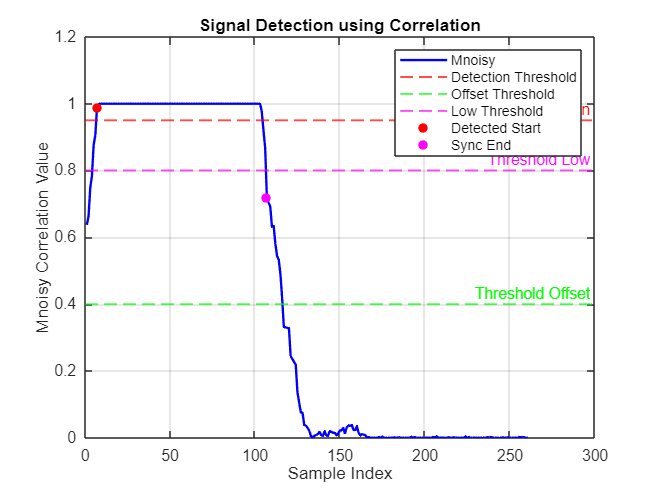

%% Plot Detection of Signal Start
figure;
plot(Mnoisy, 'b', 'LineWidth', 1.5); hold on;
yline(thres_det, '--r', 'Threshold Detection', 'LineWidth', 1.2);
yline(thres_offset, '--g', 'Threshold Offset', 'LineWidth', 1.2);
yline(thres_low, '--m', 'Threshold Low', 'LineWidth', 1.2);
scatter(imri(1), Mnoisy(imri(1)), 'ro', 'filled');  % Mark detection point
scatter(imr2, Mnoisy(imr2), 'mo', 'filled');  % Mark synchronization end
title('Signal Detection using Correlation');
xlabel('Sample Index');
ylabel('Mnoisy Correlation Value');
legend('Mnoisy', 'Detection Threshold', 'Offset Threshold', 'Low Threshold', 'Detected Start', 'Sync End');
grid on;

The next step is to delete the noise samples that were added at the beginning of the received signal (***annado***). Therefore, the code removes the initial ***annado_est*** samples from the received packet ***packet_tx***, effectively discarding the noise, and detecting the starting point of the signal, (which was what we wanted with the time synchronization) resulting in ***packet_rx***.

Then, we calculate the error in the estimated timing for the synchronization, ***err_sincr_tf*** doing  the difference between the actual number of noise samples added (***annado***) and the estimated number of noise samples (***annado_est***). As we have explained, this value indicates how accurately the algorithm has synchronized with the start of the signal.

Finally,  we add padding to the received packet to account for potential estimation errors (***paquete_rx***) and we calculate the number of symbols based on the modulation rate and the number of bits in the packet (***Nsymb***), that we will use later for demodulation.

if (annado_est > 0)
   	packet_rx = packet_tx(annado_est+1:end); % We remove the samples that are only noise
   else
      packet_rx = packet_tx; % We don't remove anything because the estimated packet packet_tx is correct from the begining
end

err_sincr_tf = annado - annado_est;
     
packet_rx = [packet_rx zeros(1,5*MaxAnnado)]; % We add some zeros at the end in case we have made a mistake a need more samples.   

Nsymb = ceil(Ndata/bits_disp);%We calculate the total number of symbols	

In the next graph we are represneting th signal before and after synchronization, where we can see the system is adjusting the begining of the signal, removing the noise.

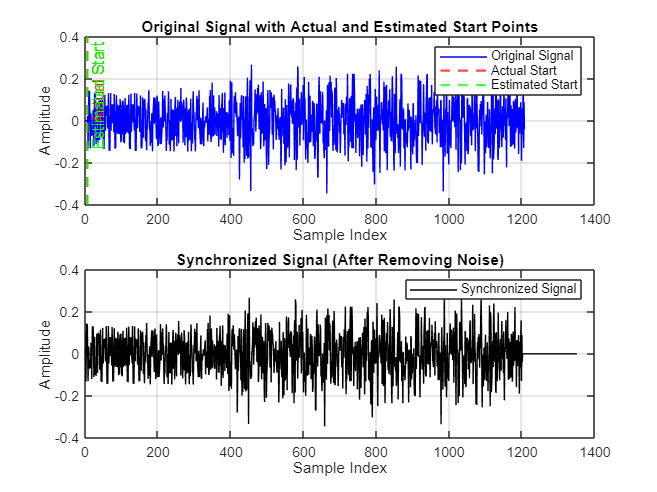

%% Plot Signal Before and After Synchronization
figure;
subplot(2,1,1);
plot(real(packet_tx), 'b'); hold on;
xline(annado, '--r', 'Actual Start', 'LineWidth', 1.5);
xline(annado_est, '--g', 'Estimated Start', 'LineWidth', 1.5);
title('Original Signal with Actual and Estimated Start Points');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Original Signal', 'Actual Start', 'Estimated Start');
grid on;

subplot(2,1,2);
plot(real(packet_rx), 'k');
title('Synchronized Signal (After Removing Noise)');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Synchronized Signal');
grid on;

The next sep is to correct the frequency offset, which was our main objetive since the first moment. For doing this, we already have the information needed, which is the estimated epsilon "***epsilon_est***", therefore, we only need to add this estimation to the frequency of the received packet: 

packet_rxc = packet_rx .* exp(-2*j*pi*epsilon_est*(1/N)*(1:length(packet_rx))); %Corrected packet.

The original signal is plotted against the one with the frequency correction. Looking at the graph below, it is clear that after the frequency correction, the preamble has the perfect, constant and synchronized pattern that had the original signal before transmission, which reflects how the synchronization has been properly carried out.

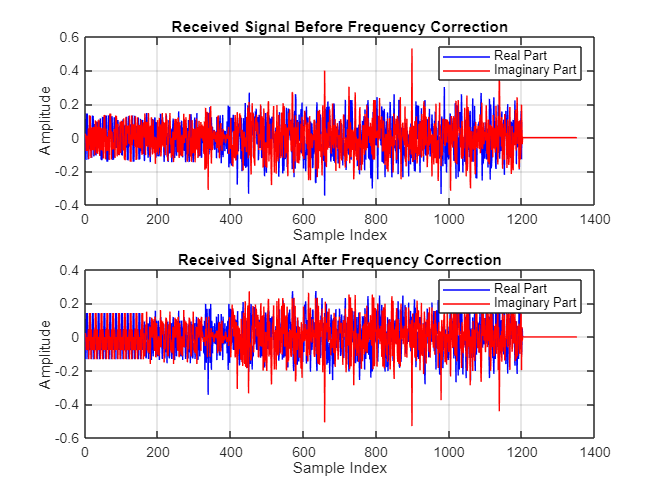

%% Plot Before and After Frequency Correction
figure;
subplot(2,1,1);
plot(real(packet_rx), 'b'); hold on;
plot(imag(packet_rx), 'r');
title('Received Signal Before Frequency Correction');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Real Part', 'Imaginary Part');
grid on;

subplot(2,1,2);
plot(real(packet_rxc), 'b'); hold on;
plot(imag(packet_rxc), 'r');
title('Received Signal After Frequency Correction');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Real Part', 'Imaginary Part');
grid on;

Finally, to finish this section, we can calculate the error when reestimating the frequency offset in the synchronization, and as we can see in the results presented below, the error is minimum, we had introduced and offset of 0.25, and basically the epsilon we have estimated is that 0.25, with an error of $5\ldotp 55\times {10}^{-17}$, which is aproximately an error of 0. This means that the synchronization has been properly made. 

if (annado == annado_est) 
      message = ['The packet has been syncronized. Estimated Epsilon: ' num2str(epsilon_est) '(Error:' num2str(Epsilon - epsilon_est) ')'];
   else
      message = ['E. sincr.: ' num2str(annado - annado_est) ' samples. Estimated Epsilon: ' num2str(epsilon_est) '(Error:' num2str(Epsilon - epsilon_est) '). Eps. Reestimado:' num2str(epsilon_est + epsilon_rest) '(Error:' num2str(Epsilon - epsilon_est - epsilon_rest) ').'];
      counterPsinSync = counterPsinSync + 1;
end 
   disp(message);

The packet has been syncronized. Estimated Epsilon: 0.25(Error:5.5511e-17)


## 4. Data demodulation. 

Once synchronization has been corrected at the receiver, we can proceed with the channel estimation, finishing this module by verifying that the receiver has been properly synchronized by making a channel estimation and verifying that the received bits are equal to the ones we have transmitted in the first section of this module. It's important to reflect the fact that frequency offset corrections are applied to the received packet before estimating the channel. This step is essential for achieving an accurate channel estimation, as any frequency offset would distort the proper alignment of the OFDM subcarriers, which in turn would affect the accuracy of the channel response estimation.

First, we do the estimation channel like we did in the previous module 1, getting ***H_est:***

pos_pilotos = 0; %We are not using reestimation, so is not necessary
H_est = estimatechannelDFT(packet_rxc,N,6,6,pos_pilotos,321,161,2,32,ref);

H_est = [0 H_est(1:26) zeros(1,11) H_est(27:end)];  % We are completing the signal with zeros


Finally, we use the Zero Forcing method (like in module 1) to make the estimation of the transmitted symbols using the estimated channel ***H_est***.

% Receive the packet
output_data = [];
[cZF,output_data,rate,n_s,rel] = receivepack80211aZFP(packet_rxc,Nsymb,Rate,H_est);

Once we have the ***output_data ***that corresponds to the estimation we have made of the transmitted bits, we can calculate the number of incorrect bits just by making the difference between the original data we have sent "***input_data***", and the estimated data "***output_data***", verifying how we have properly syncronized the system, since the incorrect bits obtained are zero. 


if (isempty(output_data))
 		disp('Incorrect packet received');
 		
else  		
  if (length(output_data) < Ndata)
     Ndat = length(output_data)
  else
     Ndat = Ndata;
  end 
  
  nerrors = sum(abs(input_data(1:Ndat) - output_data(1:Ndat)));

  partial = partial +  nerrors;

end 
message = ['Number of incorrect bits in packet number ' num2str(1) ' --> ' num2str(nerrors) ' .'];
disp(message);

Number of incorrect bits in packet number 1 --> 0 .
